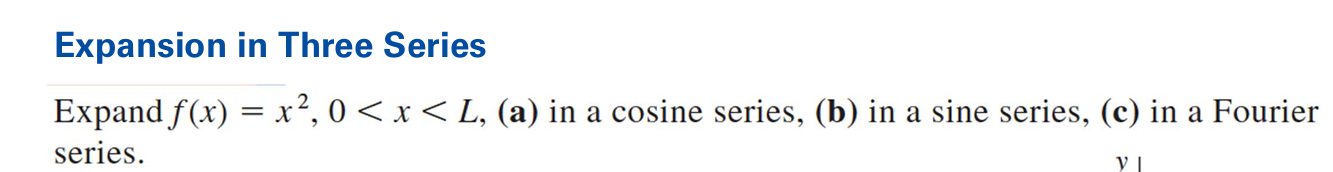

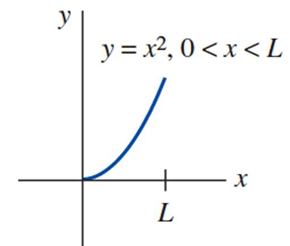

clear;clf;
syms x n;
assume(n,"integer")
f = x^2;
a0 = eval((2/2)*int(f,x,[0 2]))

a0 = 2.6667

an = simplify((2/2)*int(f*cos(n*pi*x/2),x,[0 2]))

$$an = \frac{16\,{\left(-1\right)}^{n}}{n^{2}\,\pi^{2}}$$

f0 = an*cos(n*pi*x/2);

**Number of harmonics**

harm = 20;

**Plot graph even expansion**

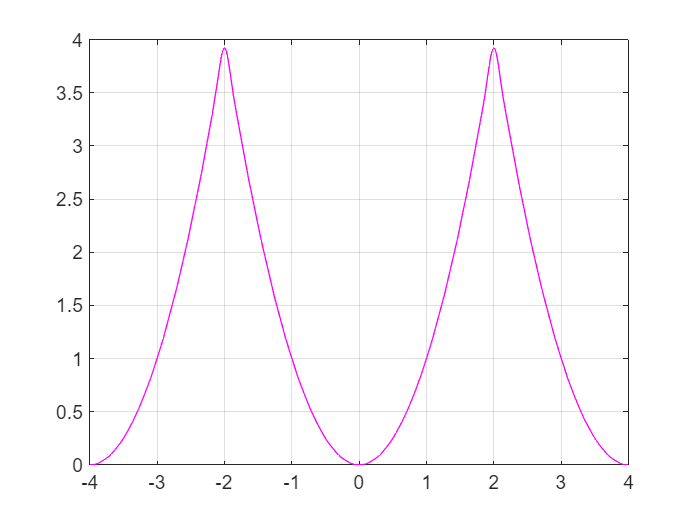

fC = a0/2+symsum(f0,n,1,harm);
fplot(fC,[-4 4],'m'); grid on

**(b)**

bn = simplify((2/2)*int(f*sin(n*pi*x/2),x,[0 2]));

**Plot graph odd expension**

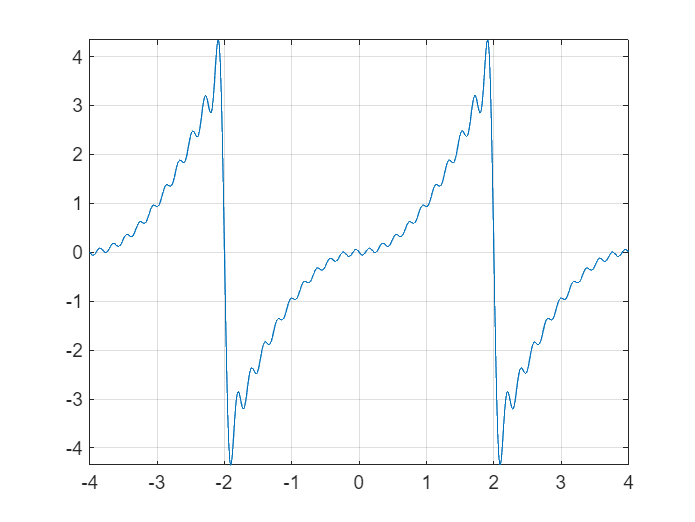

fS = bn*sin(n*pi*x/2);
fx = symsum(fS,n,1,harm);
figure
fplot(fx,[-4 4]); grid on

**(c)**

a0 = eval((2/2)*int(f,x,[0 2]))

a0 = 2.6667

an = simplify((2/2)*int(f*cos(n*pi*x),x,[0 2]))

$$an = \frac{4}{n^{2}\,\pi^{2}}$$

bn = simplify((2/2)*int(f*sin(n*pi*x),x,[0 2]))

$$bn = -\frac{4}{n\,\pi }$$

f0 = an*cos(n*pi*x)+bn*sin(n*pi*x);

**Plot graph periodic extension**

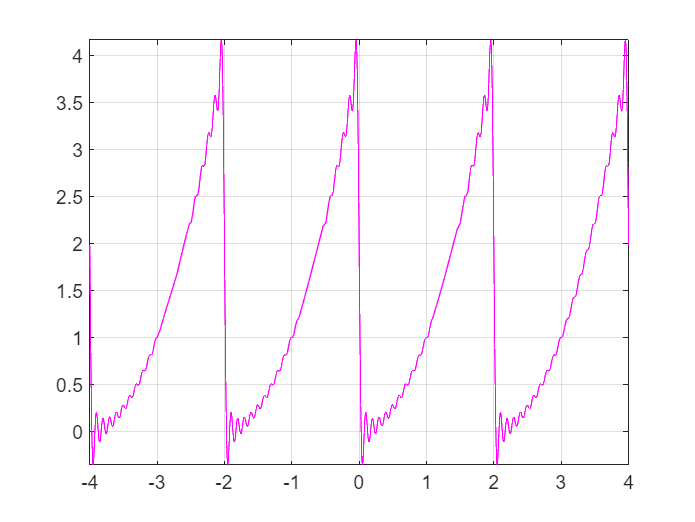

fx = a0/2+symsum(f0,n,1,harm);
fplot(fx,[-4 4],'m'); grid on

**Find the Fourier series of f(x)  = x^2 , 0 < x <= 4**

a0 = eval((2/4)*int(f,x,[0 4]))

a0 = 10.6667

an = simplify((2/4)*int(f*cos(n*pi*x/2),x,[0 4]))

$$an = \frac{16}{n^{2}\,\pi^{2}}$$

bn = simplify((2/4)*int(f*sin(n*pi*x/2),x,[0 4]))

$$bn = -\frac{16}{n\,\pi }$$

f0 = an*cos(n*pi*x/2)+bn*sin(n*pi*x/2)

$$f0 = \frac{16\,\cos\left(\frac{\pi \,n\,x}{2}\right)}{n^{2}\,\pi^{2}}-\frac{16\,\sin\left(\frac{\pi \,n\,x}{2}\right)}{n\,\pi }$$

Plot graph

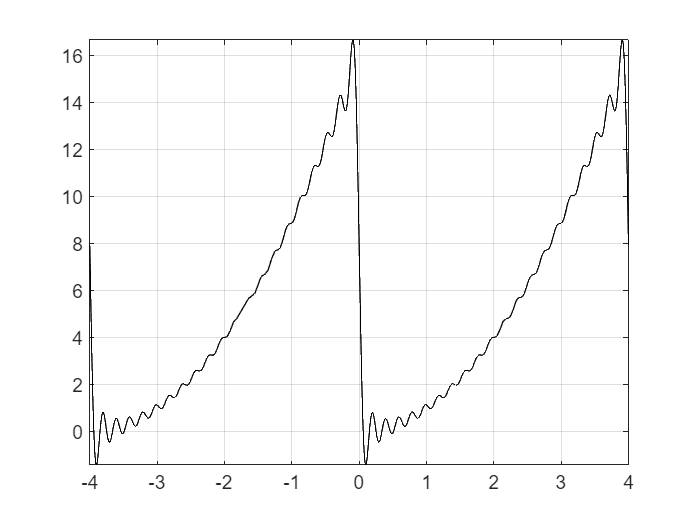

fx = a0/2+symsum(f0,n,1,harm);
fplot(fx,[-4 4],'k'); grid on